# Analisi Consumi Energetici (Tetuan City)

**Candidato: ***Stefano Di Lena.*

## Introduzione e Preprocessing dei Dati

Carichiamo il dataset reale (Tetuan City Power Consumption).

L'obiettivo è identificare un modello dinamico che leghi la temperatura (*u*) al consumo energetico (*y*)

Poiche i consumi umani seguono cicli giornalieri rigorosi, aggiungiamo due ngressi artificiali (seno e coseno del tempo) per informare il modello se è Giorno o Notte.

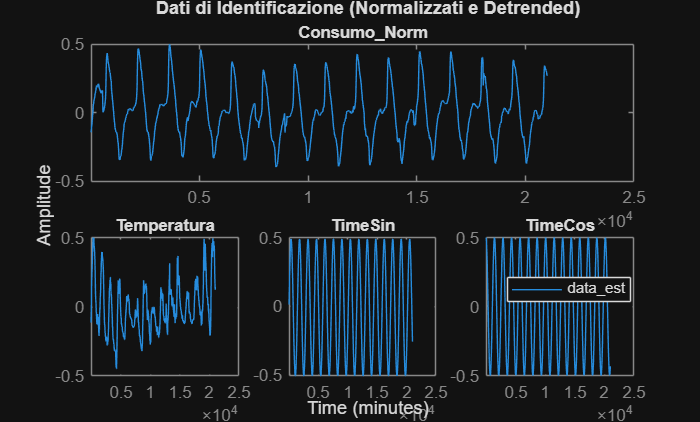

clear; clc; close all;

% --- 1. CARICAMENTO DATI ---
filename = 'Tetuan City Power Consumption.csv';
RawData  = readmatrix(filename, 'NumHeaderLines', 1);

% Selezione Variabili Grezze
% Col 2: Temperatura; 
% Col 7: Consumo Zona 1, Col 8: Consumo Zona 2, Col 9: Consumo Zona 3.

%inverno:
%StartRow = 1;

%estate:
StartRow = 30000; 

N_samples = 3000; % Prendiamo 3 settimane

u_temp = RawData(StartRow:(StartRow + N_samples), 2); 
y_raw  = RawData(StartRow:(StartRow + N_samples), 9);

% --- 2. FEATURE ENGINEERING (Ciclicità Giornaliera) ---
% Campionamento: 10 minuti -> 6 campioni/ora * 24 ore = 144 campioni/giorno
SamplesPerDay = 144; 
k = (1:length(u_temp))';

% Creazione segnali armonici per catturare l'orario (Giorno/Notte)
u_time_sin = sin(2 * pi * k / SamplesPerDay);
u_time_cos = cos(2 * pi * k / SamplesPerDay);

% Matrice Ingressi Aumentata: [Temperatura, Sin_Time, Cos_Time]
u_total = [u_temp, u_time_sin, u_time_cos];

% --- 3. NORMALIZZAZIONE (Min-Max) ---
% Essenziale per la convergenza degli algoritmi non lineari (NLARX)
u_norm = (u_total - min(u_total)) ./ (max(u_total) - min(u_total));
y_norm = (y_raw - min(y_raw)) ./ (max(y_raw) - min(y_raw));

% Creazione Oggetto IDDATA
Ts = 10; % Tempo di campionamento in minuti
data = iddata(y_norm, u_norm, Ts);
data.InputName = {'Temperatura', 'TimeSin', 'TimeCos'};
data.OutputName = 'Consumo_Norm';
data.TimeUnit = 'minutes';

% Divisione: 70% Stima (Identification), 30% Validazione
Nt = floor(0.7 * size(data,1));
data_est = data(1:Nt);
data_val = data(Nt+1:end);

% Detrending (Rimozione valor medio per lavorare sulle variazioni)
data_est = detrend(data_est);
data_val = detrend(data_val);

% Plot dei dati processati
figure
plot(data_est)
title('Dati di Identificazione (Normalizzati e Detrended)')
legend('Location','best')

## Selezione dell'Ordine Ottimo

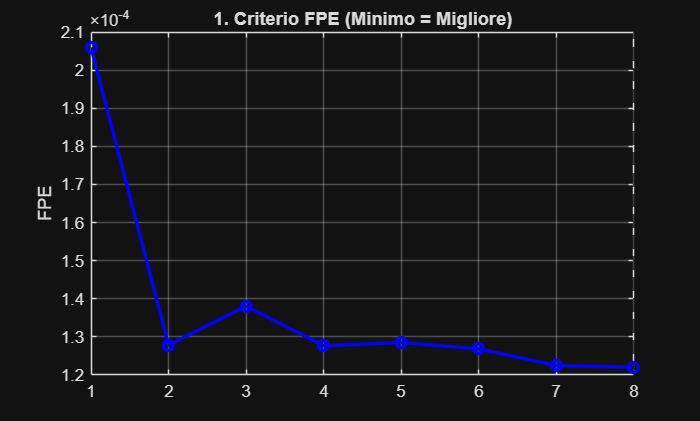

%% CONFRONTO DEI 4 CRITERI PRINCIPALI DI SELEZIONE (ARMAX)
max_order = 8; % Alziamo a 8 per vedere bene dove vanno a parare
FPE = nan(max_order, 1);
AIC = nan(max_order, 1);

N = length(data_est.y); % Numero di campioni

for n = 1:max_order
    try
        m = armax(data_est, [n [n n n] n [1 1 1]]);
        
        if isstable(m)
            % 1. FPE (Final Prediction Error)
            FPE(n) = m.Report.Fit.FPE;
            
            % 2. AIC (Akaike Information Criterion)
            AIC(n) = m.Report.Fit.AIC;
        end
    catch
    end
end

%% PLOT
figure;

% 1. Grafico FPE
plot(1:max_order, FPE, '-ob', 'LineWidth', 2);
title('1. Criterio FPE (Minimo = Migliore)');
ylabel('FPE'); grid on;
[~, best_fpe] = min(FPE);
xline(best_fpe, '--k', ['Ottimo: ' num2str(best_fpe)]);

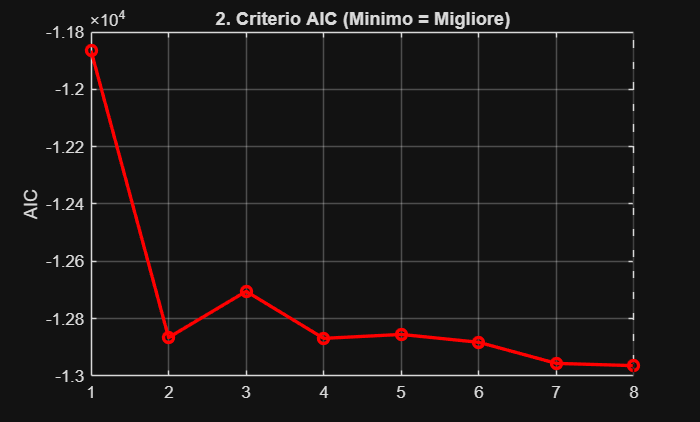


% 2. Grafico AIC
figure;
plot(1:max_order, AIC, '-or', 'LineWidth', 2);
title('2. Criterio AIC (Minimo = Migliore)');
ylabel('AIC'); grid on;
[~, best_aic] = min(AIC);
xline(best_aic, '--k', ['Ottimo: ' num2str(best_aic)]);

fprintf('FPE suggerisce: %d\n', best_fpe);

FPE suggerisce: 8


fprintf('AIC suggerisce: %d\n', best_aic);

AIC suggerisce: 8


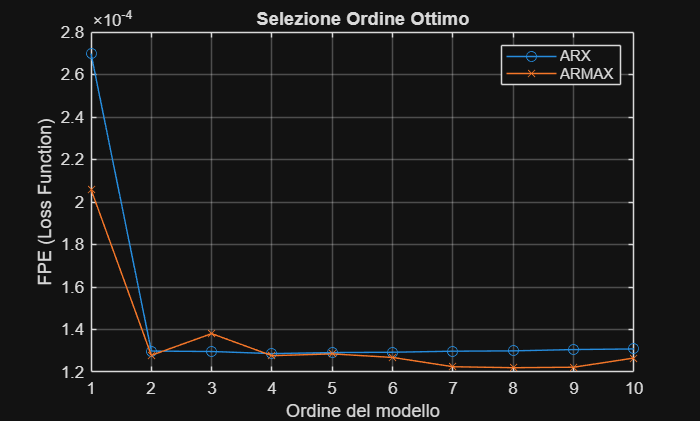

% Range di ricerca dell'ordine
max_order = 10; 
V_arx = nan(max_order,1);
V_armax = nan(max_order,1);

% Ciclo di ottimizzazione strutturale
for n = 1:max_order
    % Stima ARX [na nb nk] - nk=1 (ritardo unitario standard)
    % nb ha 3 elementi perchè hai 3 ingressi (Temp, Sin, Cos)
    m_tmp_arx = arx(data_est, [n [n n n] [1 1 1]]); 

    V_arx(n) = m_tmp_arx.Report.Fit.FPE; % Salviamo FPE

    % Stima ARMAX [na nb nc nk]
    try
        m_tmp_armax = armax(data_est, [n [n n n] n [1 1 1]]);

        if isstable(m_tmp_armax) 

            V_armax(n) = m_tmp_armax.Report.Fit.FPE;

        else
            % Se instabile, lo penalizziamo con Infinito così non viene scelto
            V_armax(n) = Inf; 
        end

    catch
        V_armax(n) = NaN; % Gestione errori di convergenza
    end
end

% Plot selezione ordine
figure
plot(1:max_order, V_arx, '-o', 1:max_order, V_armax, '-x');
legend('ARX', 'ARMAX');
xlabel('Ordine del modello'); ylabel('FPE (Loss Function)');
title('Selezione Ordine Ottimo');
grid on;



% Selezione dell'ordine che massimizza il FIT ARMAX
%[best_fit, best_n] = max(V_armax);
%[best_fit, best_n] = max(Fit_Val_ARMAX);
%fprintf('Ordine ottimo ricalcolato (Max Validation Fit): %d con Fit %.2f%%\n', best_n, best_fit);

[best_fpe_arx, best_n_arx] = min(V_arx);
fprintf('Miglior ARX: Ordine %d (FPE %.4f%%)\n', best_n_arx, best_fpe_arx);

Miglior ARX: Ordine 4 (FPE 0.0001%)



[best_fpe_armax, best_n_armax] = min(V_armax);
fprintf('Miglior ARMAX: Ordine %d (FPE %.4f%%)\n', best_n_armax, best_fpe_armax);

Miglior ARMAX: Ordine 8 (FPE 0.0001%)



% Ricalcolo i modelli finali con il nuovo ordine "sicuro"
m_arx_opt   = arx(data_est, [best_n_arx [best_n_arx best_n_arx best_n_arx] [1 1 1]]);
m_armax_opt = armax(data_est, [best_n_armax [best_n_armax best_n_armax best_n_armax] best_n_armax [1 1 1]]);

### Identificazione non lineare (NLARX)

Poiché la relazione tra temperatura e consumo può presentare saturazion, testiamo un modello **NLARX** con stimatore *Sigmoid Network*, per catturare le dinamiche non lineari che sfuggono ai modelli classici.

% NLARX con regressori standard
m_nlarx = nlarx(data_est, [best_n_armax  [best_n_armax  best_n_armax  best_n_armax ] [1 1 1]], 'idSigmoidNetwork');

## Validazione Comparativa e Baseline

Confrontiamo i modelli su nuovi dati (non usati per la stima). Proviamo anche un modello AR semplice come *Baseline*: se l'ARX o ARMAX non battono quest'ultimo la temperatura è un dato inutile.

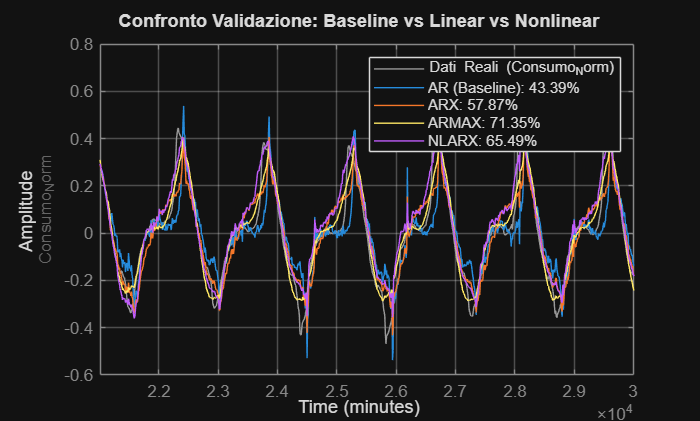

data_y_only = data_est(:, 'Consumo_Norm', []);

% 1. Modello Baseline (Solo AR - Ignora Temperatura e Orario)
m_baseline = ar(data_y_only, best_n_armax);

K = 12; % passo
% 2. Confronto Grafico (Validation Set)
figure
compare(data_val, m_baseline, m_arx_opt, m_armax_opt, m_nlarx, K); 
title('Confronto Validazione: Baseline vs Linear vs Nonlinear');
legend('Dati Reali', 'AR (Baseline)', 'ARX', 'ARMAX', 'NLARX');
grid on;

## Analisi dei Residui

Dobbiamo verificare che:

- I residui devono essere rumore bianco (scorrelati).

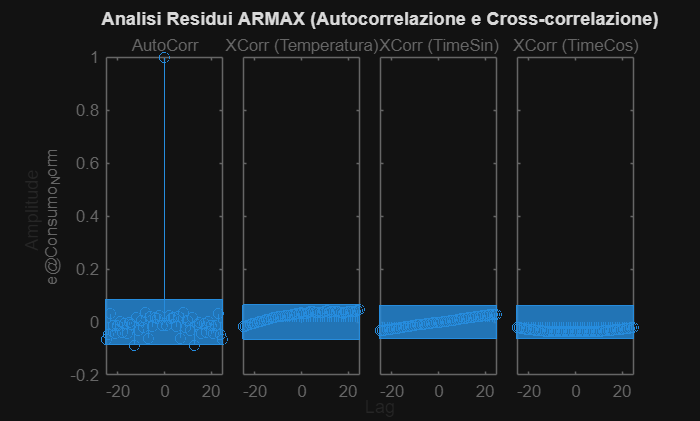

% 1. Whiteness Test (Analisi Residui) su ARMAX
figure
resid(data_val, m_armax_opt); 
title('Analisi Residui ARMAX (Autocorrelazione e Cross-correlazione)');

% Le barre devono stare dentro le linee blu di confidenza.

**Zona 1 (Quibla):** Area prevalentemente **Residenziale**.

- *Comportamento:* Segue i ritmi delle famiglie. Picchi la mattina presto e la sera. In inverno, se fa caldo fuori, la gente spegne il riscaldamento (correlazione inversa).

**Zona 2 (Smir):** Area **Turistica / Costiera**.

- *Comportamento:* È la zona "vacanze".

- *In Inverno (Gennaio - i tuoi dati):* Probabilmente è semivuota. Il consumo potrebbe essere basso, irregolare e poco correlato alla temperatura (perché ci sono poche persone). Potresti ottenere un FIT basso qui, ed è **giustificabile** ("Zona turistica fuori stagione").

- *In Estate:* Esplode di consumi per i condizionatori degli hotel.

**Zona 3 (Boussafou):** Area **Industriale / Amministrativa (Uffici)**.

- *Comportamento:* Attiva dalle 9:00 alle 17:00.

- *Fisica:* Qui l'aria condizionata (o il riscaldamento) è centralizzata e accesa **di giorno**. Quindi è molto probabile trovare una **Correlazione Diretta** (Step Response positiva) e più pulita rispetto alle case

il best_n deve seguire questa regola:

AR < ARX < ARMAX < NLARX